dataFile = 'L:\RGECO\190610\190610-R5M2286-stim1_processed.mat';
maskFile = 'L:\RGECO\190610\190610-R5M2286-LandmarksandMask.mat';
load(maskFile,'xform_isbrain')
load(dataFile,'xform_datahb');
data = squeeze(xform_datahb(:,:,1,:));

time = linspace(1,300,size(xform_datahb,4));
mask = logical(xform_isbrain);

Let's try principal component analysis (PCA) on the time course. We need to decide the definition of data. PCA will find vectors that explains the most variance amongst data. This time, we will look at variance of temporal fluctuations amongst pixels. This means each pixel will be a data point. The input to pca function should be shaped such that each row is a data point. Let's reshape the data such that each row is a pixel.

data = reshape(data,[],size(data,3));

We usually only care about variance within the brain. Thus, let's only select data that is within the brain mask.

data = data(mask,:);

Now let's conduct PCA.

[coeff,score,latent,tsquared,explained,mu] = pca(data);

The coeff variable contains coefficients for each principal component (each principal component is a column). We can see the coeff to see what sort of time course explains the most variance amongst the time courses.

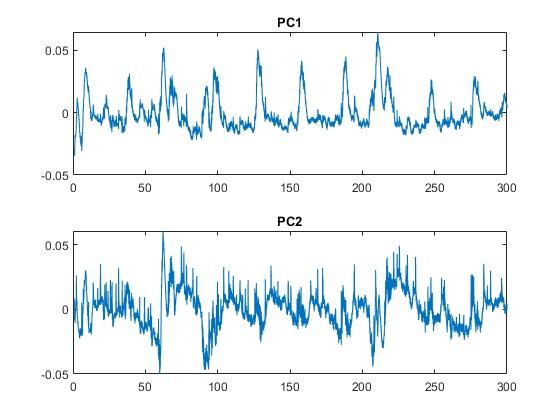

figure;
subplot(2,1,1); plot(time,coeff(:,1)); title('PC1');
subplot(2,1,2); plot(time,coeff(:,2)); title('PC2');

We can also see how much of each principal component explains the total variance by looking at 'explained' variable. The unit is in percentage.

disp(explained(1:2))

   53.2883
   10.8331



We can also see how much of each principal component is contained in each pixel by looking at 'score' variable. The 'coeff' variable describes a normalized vector while the 'score' variable describes the coordinates of the data points in the space described by those normalized vectors.

Here we will show image of the coordinates for each principal component.

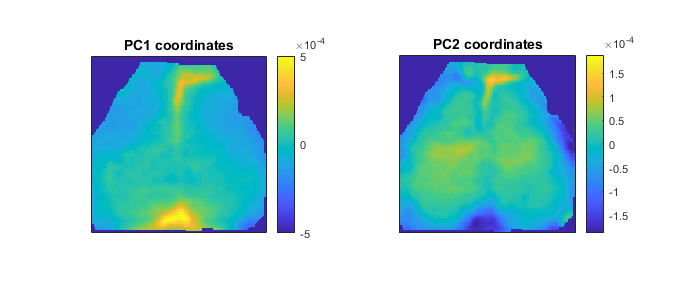

figure('Position',[100 100 700 300]);
subplot(1,2,1);
s = nan(128); s(mask) = score(:,1);
imagesc(s,[-max(abs(s(:))) max(abs(s(:)))]); axis(gca,'square'); xticks([]); yticks([]); colorbar; title('PC1 coordinates')
subplot(1,2,2);
s = nan(128); s(mask) = score(:,2);
imagesc(s,[-max(abs(s(:))) max(abs(s(:)))]); axis(gca,'square'); xticks([]); yticks([]); colorbar; title('PC2 coordinates')

From looking at the scores, it is apparent that PC1 is signal that comes mostly from vasculature. Let's try to remove the effects of PC1 from the rest of the signal.

We can convert PC1 coordinates back to original data coordinates by multiplying score of PC1 with coeff of PC1.

vascularData = score(:,1)*coeff(:,1)';

Remove vascularData from the originalData.

dataNoVasculature = data - vascularData;

Finally we reshape the data to 3D array to regain spatial information.

data2 = nan(128*128,size(data,2));
data2(mask,:) = data;
data2 = reshape(data2,128,128,[]);
data = data2;

data2 = nan(128*128,size(dataNoVasculature,2));
data2(mask,:) = dataNoVasculature;
data2 = reshape(data2,128,128,[]);
dataNoVasculature = data2;

Let's see the effects of removing vasculature.

First, let's look at a pixel that is around somatosensory cortex.

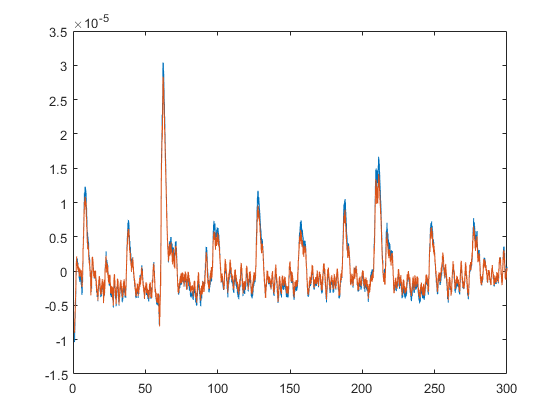

figure;
plot(time,squeeze(data(79,79,:))); hold on;
plot(time,squeeze(dataNoVasculature(79,79,:)));

 Let's also at a pixel that is on the medial vasculature.

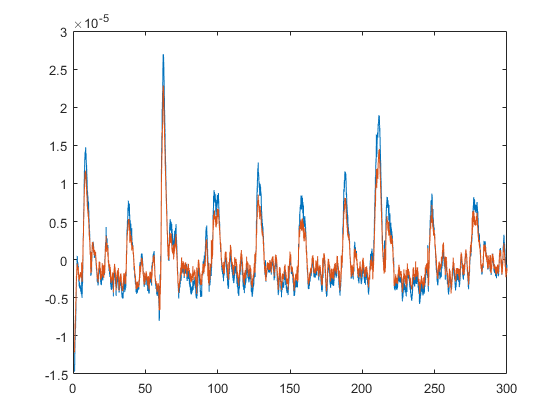

figure;
plot(time,squeeze(data(64,64,:))); hold on;
plot(time,squeeze(dataNoVasculature(64,64,:)));

Let's look at a video.

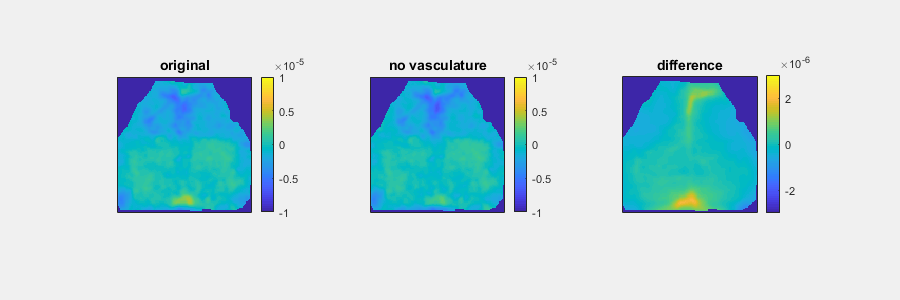

Index in position 3 exceeds array bounds (must not exceed 5000).

f = figure('Position',[100 100 900 300]);
for i = 1:numel(data)
    subplot(1,3,1); imagesc(data(:,:,i),[-10 10]*1E-6); axis(gca,'square'); xticks([]); yticks([]); colorbar; title('original')
    subplot(1,3,2); imagesc(dataNoVasculature(:,:,i),[-10 10]*1E-6); axis(gca,'square'); xticks([]); yticks([]); colorbar; title('no vasculature')
    subplot(1,3,3); imagesc(data(:,:,i)-dataNoVasculature(:,:,i),[-3 3]*1E-6); axis(gca,'square'); xticks([]); yticks([]); colorbar; title('difference')
    pause(0.1);
    set(f,'Visible','on')
end